## Example 2-3

#### 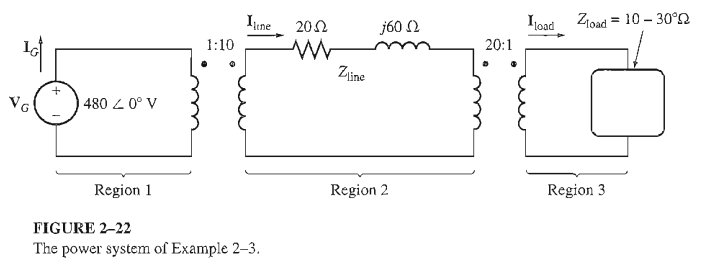

#### A simple power system is shown in Figure 2 - 22. This system contains a 480-V generator connected to an ideal 1:10 step-up transformer, a transmission line,  an ideal 20:1 step-down transformer, and a load. The impedance of the transmission line is  20 + j60 ohms. and the impedance of the load is 10∠30° ohms. The base values for this system are  chosen to be 480 V and 10 kVA at the generator. 

#### (a) Find the base voltage, current, impedance, and apparent power at every point in  the power system.  

#### (b) Convert this system to its per-unit equivalent circuit.  

#### (c) Find the power supplied to the load in this system.  

#### (d) Find the power lost in the transmission line.  

**(a) 計算每個區域的基準電壓、電流、阻抗及視在功率**

- **基準電壓**： 基準電壓就是我們在電路中各個區域的標準電壓。由於系統包含兩個變壓器，所以我們要考慮它們的變比。

- 在發電機那邊的區域，基準電壓已知為 480 伏特。

- 經過第一個 1:10 的變壓器後，基準電壓會被放大 10 倍，因此變成 4800 伏特。

- 經過第二個 20:1 的變壓器後，基準電壓會被縮小 20 倍，變成 240 伏特。

- **基準電流**： 基準電流代表電路中基準條件下的標準電流，計算公式是基準視在功率除以基準電壓。

- 在發電機那邊，基準電流是 20.83 安培。

- 在第一個變壓器之後（高壓側），電壓被放大 10 倍，電流被縮小 10 倍，因此基準電流是 2.083 安培。

- 經過第二個變壓器後，電壓縮小 20 倍，電流會被放大 20 倍，所以基準電流是 41.67 安培。

- **基準阻抗**： 基準阻抗就是電壓平方除以視在功率，它在每個區域都不同。

- 在發電機那邊，基準阻抗是 23.04 歐姆。

- 在高壓區域，基準阻抗變成 2304 歐姆。

- 在低壓負載那邊，基準阻抗是 5.76 歐姆。

**(b) 將系統轉換成每單位值等效電路**

每單位值的轉換是將實際阻抗除以基準阻抗。這樣做是為了讓不同電壓層次的阻抗變得可以直接比較。

- **傳輸線阻抗的每單位值**： 傳輸線阻抗是 20 加上 j60 歐姆，我們將它除以基準阻抗 2304 歐姆，得到 0.0087 加上 j0.026。

- **負載阻抗的每單位值**： 負載阻抗是 10 歐姆，相角是負 30 度。將它除以基準阻抗 5.76 歐姆，得到每單位值 1.736，相角是負 30 度。

**(c) 計算負載接收的功率**

為了計算負載接收的功率，我們需要知道負載端的每單位電壓和電流。

- **負載的每單位電流**： 負載的每單位電壓設定為 1，因此負載的每單位電流可以通過電壓除以每單位負載阻抗來計算。結果是 0.576，相角是 30 度。

- **負載的每單位視在功率**： 每單位視在功率是每單位電壓乘以每單位電流的共軛。結果是 0.576，每單位視在功率的相角是負 30 度。

- **實際負載功率**： 實際功率是每單位視在功率乘以基準視在功率 10 kVA。結果是 5.76 kVA，這是負載接收到的實際功率。

**(d) 計算傳輸線中的功率損失**

我們也可以計算傳輸線中的功率損失，使用的是傳輸線中的每單位電流和實際電阻。

- **傳輸線中的每單位電流**： 我們將負載的每單位電壓除以負載的每單位阻抗加上傳輸線的每單位阻抗，得到傳輸線的每單位電流是 0.571，相角是 33.1 度。

- **每單位功率損失**： 傳輸線中的功率損失等於每單位電流的平方，乘以傳輸線的每單位阻抗的實部。結果是 0.00284 每單位功率。

- **實際功率損失**： 最後，我們將每單位功率損失乘以基準視在功率 10 kVA，結果是 28.4 瓦，這是傳輸線中的實際功率損失。

**結論：**

- 負載接收的功率是 5.76 kVA。

- 傳輸線中的功率損失是 28.4 瓦。

### 2-3 by chatGPT

% Given values
V_base_gen = 480;          % Base voltage at generator (V)
S_base = 10e3;             % Base apparent power (10 kVA)
Z_line = 20 + 1i*60;       % Transmission line impedance (Ohms)
Z_load = 10*exp(-1i*pi/6); % Load impedance (10∠-30° Ohms)

% Transformer turns ratio
N1 = 1/10;   % Step-up transformer ratio
N2 = 20/1;   % Step-down transformer ratio

% (a) Base values at every point in the system
% Base voltage
V_base_1 = V_base_gen;          % Base voltage in region 1
V_base_2 = V_base_1 / N1;       % Base voltage in region 2 (after step-up)
V_base_3 = V_base_2 / N2;       % Base voltage in region 3 (after step-down)

% Base current at every point
I_base_1 = S_base / V_base_1;   % Base current in region 1
I_base_2 = S_base / V_base_2;   % Base current in region 2
I_base_3 = S_base / V_base_3;   % Base current in region 3

% Base impedance at every point
Z_base_1 = V_base_1^2 / S_base; % Base impedance in region 1
Z_base_2 = V_base_2^2 / S_base; % Base impedance in region 2
Z_base_3 = V_base_3^2 / S_base; % Base impedance in region 3

% Display results for part (a)
fprintf('Base voltage (V) in Region 1: %.2f V\n', V_base_1);

Base voltage (V) in Region 1: 480.00 V


fprintf('Base voltage (V) in Region 2: %.2f V\n', V_base_2);

Base voltage (V) in Region 2: 4800.00 V


fprintf('Base voltage (V) in Region 3: %.2f V\n\n', V_base_3);

Base voltage (V) in Region 3: 240.00 V




fprintf('Base current (A) in Region 1: %.2f A\n', I_base_1);

Base current (A) in Region 1: 20.83 A


fprintf('Base current (A) in Region 2: %.2f A\n', I_base_2);

Base current (A) in Region 2: 2.08 A


fprintf('Base current (A) in Region 3: %.2f A\n\n', I_base_3);

Base current (A) in Region 3: 41.67 A




fprintf('Base impedance (Ohms) in Region 1: %.2f Ohms\n', Z_base_1);

Base impedance (Ohms) in Region 1: 23.04 Ohms


fprintf('Base impedance (Ohms) in Region 2: %.2f Ohms\n', Z_base_2);

Base impedance (Ohms) in Region 2: 2304.00 Ohms


fprintf('Base impedance (Ohms) in Region 3: %.2f Ohms\n\n', Z_base_3);

Base impedance (Ohms) in Region 3: 5.76 Ohms




% (b) Convert system to per-unit equivalent circuit
Z_line_pu = Z_line / Z_base_2;   % Line impedance in per-unit
Z_load_pu = Z_load / Z_base_3;   % Load impedance in per-unit

fprintf('Per-unit line impedance: %.4f + j%.4f pu\n', real(Z_line_pu), imag(Z_line_pu));

Per-unit line impedance: 0.0087 + j0.0260 pu


fprintf('Per-unit load impedance: %.4f∠%.2f° pu\n\n', abs(Z_load_pu), angle(Z_load_pu) * 180/pi);

Per-unit load impedance: 1.7361∠-30.00° pu




% (c) Find power supplied to the load
V_load_pu = 1;  % Assume per-unit voltage across load is 1 pu (100% rated voltage)
I_load_pu = V_load_pu / Z_load_pu;  % Per-unit load current

S_load_pu = V_load_pu * conj(I_load_pu);  % Per-unit apparent power delivered to the load
S_load = S_load_pu * S_base;              % Actual power delivered to the load (in VA)

fprintf('Power supplied to load: %.2f VA\n\n', abs(S_load));

Power supplied to load: 5760.00 VA




% (d) Power lost in the transmission line
I_line_pu = V_load_pu / (Z_load_pu + Z_line_pu); % Per-unit current in transmission line
P_loss_pu = abs(I_line_pu)^2 * real(Z_line_pu);  % Per-unit real power loss
P_loss = P_loss_pu * S_base;                     % Actual power loss in transmission line (in W)

fprintf('Power lost in transmission line: %.2f W\n', P_loss);

Power lost in transmission line: 28.98 W


### 2-3 by teacher

Vbase1 = 480;
Sbase = 10000;
Zline = 20+60i;
VG = 480;
Zload = 10;

% generator zoom
Ibase1 = Sbase/Vbase1;
Zbase1 = Vbase1/Ibase1;
disp (['Ibase1 = ' ,num2str(Ibase1), '  Zbase1=' ,num2str(Zbase1)]);

Ibase1 = 20.8333  Zbase1=23.04


a = 1/10;

% transmission line zoom
Vbase2 = Vbase1/a;
Ibase2 = Sbase/Vbase2;
Zbase2 = Vbase2/Ibase2;
disp (['Ibase2 = ' ,num2str(Ibase2), '  Zbase2=' ,num2str(Zbase2)]);

Ibase2 = 2.0833  Zbase2=2304


a = 20;

% Load zoom
Vbase3 = Vbase2/a;
Ibase3 = Sbase/Vbase3;
Zbase3 = Vbase3/Ibase3;
disp (['Ibase3 = ' ,num2str(Ibase3), '  Zbase3=' ,num2str(Zbase3)]);

Ibase3 = 41.6667  Zbase3=5.76



VGpu = VG/Vbase1;
% Zlinepu = Zline/Zbase2;
Zlinepu = abs(Zline)/Zbase2;
theta = angle(Zline);
[Rlinepu, Xlinepu] = pol2cart(theta, Zlinepu);
disp (['Zlinepu = ' ,num2str(Rlinepu),' +j',num2str(Xlinepu)]);

Zlinepu = 0.0086806 +j0.026042



Zloadpup = Zload/Zbase3;
disp (['Zloadpu = ' ,num2str(Zloadpup), '/_30']);

Zloadpu = 1.7361/_30



[Rpu, Xpu] = pol2cart(deg2rad(30), Zloadpup);
Zloadpu = Zloadpup*exp(1j*deg2rad(30));
Ztotpu = Zlinepu+Zloadpu;
disp (['Ztotpu = ' , num2str(real(Ztotpu)),' +j',num2str(imag(Ztotpu))]);

Ztotpu = 1.531 +j0.86806


Ipu = VGpu/[abs(Ztotpu)]; 
disp (['Ipu = ' , num2str(Ipu),'/_-',num2str(rad2deg(angle(Ztotpu)))]);

Ipu = 0.5682/_-29.5532



Ploadpu = Ipu^2 * Rpu;
disp (['Ploadpu = ' , num2str(Ploadpu)]);

Ploadpu = 0.48542


Pload = Ploadpu * Sbase;
disp (['Pload = ' , num2str(Pload)]);

Pload = 4854.1562


Plinepu = Ipu^2 * Rlinepu;
disp (['Plinepu = ' , num2str(Plinepu)]);

Plinepu = 0.0028025


Pline = Plinepu * Sbase;
disp (['Pline = ' , num2str(Pline)]);

Pline = 28.0255
